% B = 12;
% N = 1024;
% delta = 2/2^B;
% fs = 100E3;
% fx = fs*1/N;
% t = [0:2^B*N-1]/fs;
% y = sin(2*pi*fx*t);
% y = round(y/delta) * delta;
% s = fft(y);
% s = s(1:N/2+1);
% s = abs(s)/N;
% s(2:end-1) = 2*s(2:end-1);
% 
% f = (0:length(s) -1 )/N;
% 
% figure()
% plot(f(1:N/2+1), 20*log10(s(1:N/2+1)));

%%
% figure
% histogram(y, 2^B)
clear

### 采样数据量估计

N = 15;
beta = 0.1;
Zalpha = 1.96;
Fs = 2E6;                                   % sample rate: 2MHz

% Requirements in hardware
N_record = (pi*2^(N-1)*Zalpha^2) / (beta^2);
MemorySize = N_record * 4 / 1024^2;         % unit: MB
TestTime = N_record / Fs;                   % unit: s

% UART Speed
BaudRate = 256000;
TransferTime = (MemorySize*1024^2*8 / 115200) / 3600;   % unit: hr

fprintf("Record Number: %.1f MPoints; Required Memory Size: %.1f MB;\n", N_record/1E6, MemorySize);

Record Number: 19.8 MPoints; Required Memory Size: 75.4 MB;


fprintf("Sampling Time: %.1f s; Transaction Time: %.1f hr;\n", TestTime, TransferTime);

Sampling Time: 9.9 s; Transaction Time: 1.5 hr;


### 从 .mat 文件中数据读取

len_seg = 125000;
num_seg = 168;
Vout_array = zeros([len_seg, num_seg]);
Gain = 15.3111;
tic
for i = 1:num_seg
    FileName = ['16Hz-',num2str(i),'.mat'];
    data_N4 = ReadData(FileName);
    Vout_array(:, i) = Calibration(data_N4, Gain);
    if (mod(i, floor(num_seg/10)) == 0)
        fprintf("Process: %d %\n", 10*i/floor(num_seg/10));
    end
end

Process: 10 Process: 20 Process: 30 Process: 40 Process: 50 Process: 60 Process: 70 Process: 80 Process: 90 Process: 100 

toc

历时 132.088476 秒。


### 将数据量化为数字码

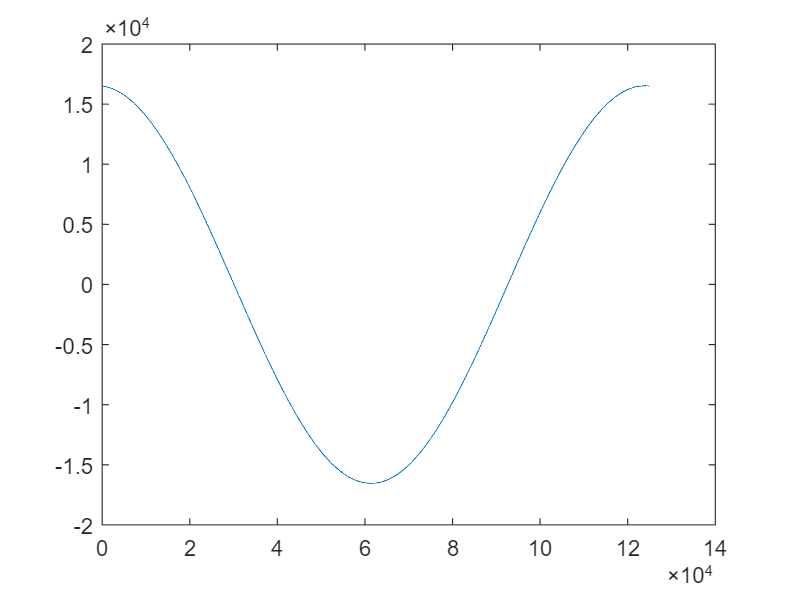

Vref = 1.8;
LSB = Vref / 2^(N-1);
MAX_CODE = 2^(N-1)-1;
MIN_CODE = -2^(N-1);

% quantization
Negative_array = Vout_array < 0;
quan_array = floor(Vout_array / LSB);

plot(quan_array(:,1))


% 消除超出范围的数字码
Max_array = quan_array>=MAX_CODE 

Max_array = 125000×168 logical 数组
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

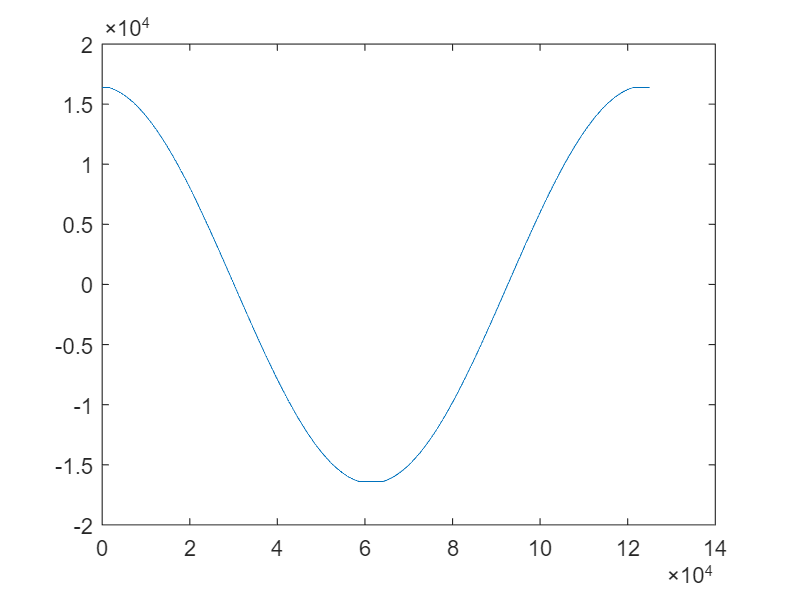

Min_array = quan_array<=MIN_CODE;
quan_array_fit = Max_array*MAX_CODE + Min_array*MIN_CODE + (~Max_array).*(~Min_array).*quan_array;

plot(quan_array_fit(:,1))

### 统计每个数字码出现的次数和概率

NUM_TOT = len_seg * num_seg;
quan_tb = tabulate(quan_array_fit(:));
quan_tb = array2table(quan_tb, 'VariableNames',{'Code', 'Count', 'Percent'})

quan_tb = 32768×3 table
     Code       Count       Percent 
    ______    __________    ________

    -16384    1.0068e+06      4.7945
    -16383          2627     0.01251
    -16382          3003      0.0143
    -16381          2656    0.012648
    -16380          2481    0.011814
    -16379          2594    0.012352
    -16378          2923    0.013919
    -16377          2503    0.011919
    -16376          2534    0.012067
    -16375          2749     0.01309
    -16374          2403    0.011443
    -16373          2628    0.012514
    -16372          2602     0.01239
    -16371          2903    0.013824
    -16370          2505    0.011929
    -16369          2815    0.013405


% static_result = struct('Code', MIN_CODE:MAX_CODE)


### 计算转移曲线 by p.d.f

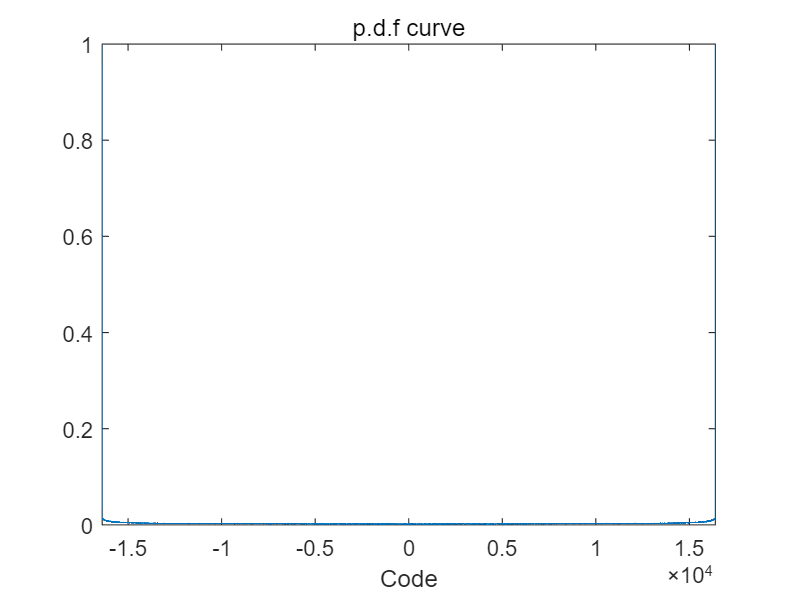

% Plot pdf curve
plot(quan_tb.Code, quan_tb.Percent);
xlabel('Code');
title('p.d.f curve');
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])

### 计算转移曲线 by c.d.f

% Plot cdf curve
quan_tb.Cdf = (cumsum(quan_tb.Percent)) / 100

quan_tb = 32768×4 table
     Code       Count       Percent       Cdf   
    ______    __________    ________    ________

    -16384    1.0068e+06      4.7945    0.047945
    -16383          2627     0.01251     0.04807
    -16382          3003      0.0143    0.048213
    -16381          2656    0.012648     0.04834
    -16380          2481    0.011814    0.048458
    -16379          2594    0.012352    0.048581
    -16378          2923    0.013919    0.048721
    -16377          2503    0.011919     0.04884
    -16376          2534    0.012067     0.04896
    -16375          2749     0.01309    0.049091
    -16374          2403    0.011443    0.049206
    -16373          2628    0.012514    0.049331
    -16372          2602     0.01239    0.049455
    -16371          2903    0.013824    0.049593
    -16370          2505    0.011929    0.049712
    -16369          2815    0.013405    0.049846


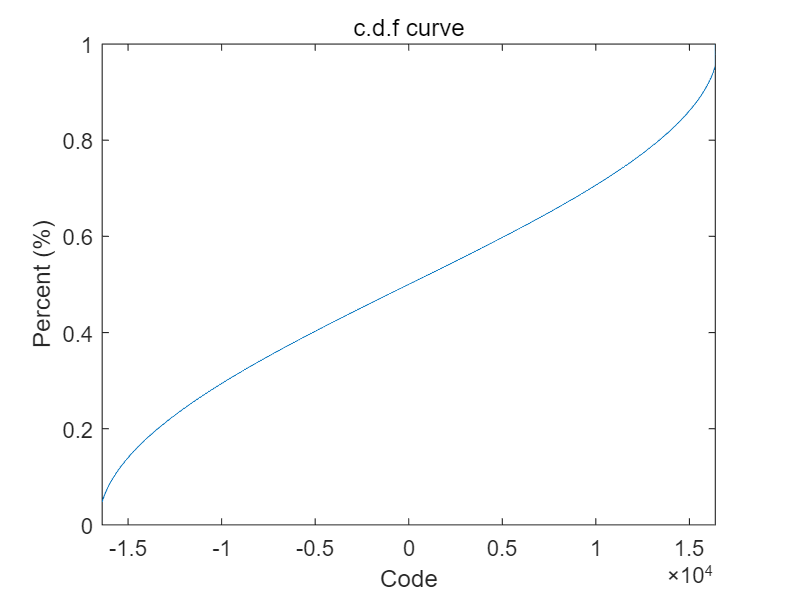

plot(quan_tb.Code, quan_tb.Cdf);
xlabel('Code');
ylabel('Percent (%)')
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])
title('c.d.f curve')

### Curve fit

% Curve Fit for A C
a_list = zeros(1,num_seg);
c_list = zeros(1,num_seg);

t = 0:1/Fs:(len_seg-1)/Fs;

myfittype = fittype('a*sin(b*t+c)+d',...
    'dependent',{'V'},'independent',{'t'},...
    'coefficients',{'a','b','c','d'})

myfittype =      General model:
     myfittype(a,b,c,d,t) = a*sin(b*t+c)+d

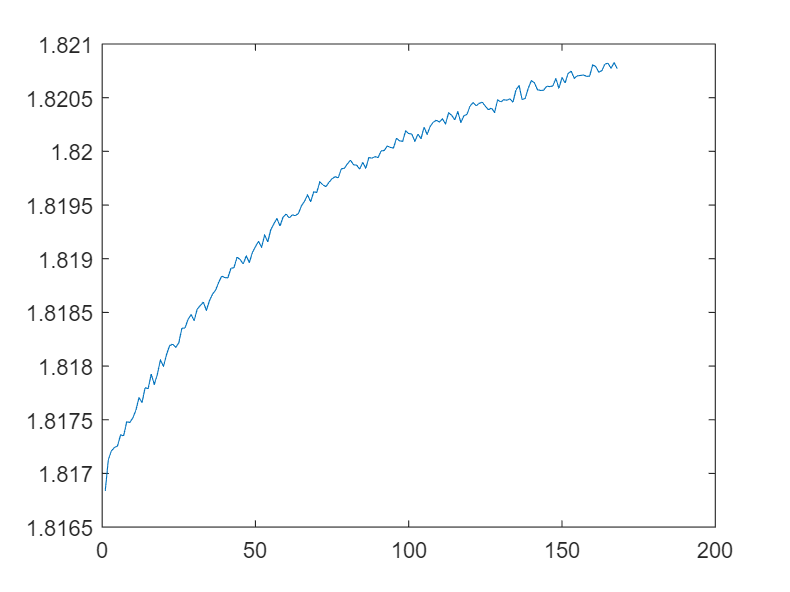

opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = [1.8 100.5 0 0];

% myfit = fit(t',V1,myfittype)

for i = 1:num_seg
    V = Vout_array(:,i);
    myfit = fit(t',V,myfittype, opts);
    a_list(i) = myfit.a;
    c_list(i) = myfit.d;
end
figure
plot(abs(a_list))

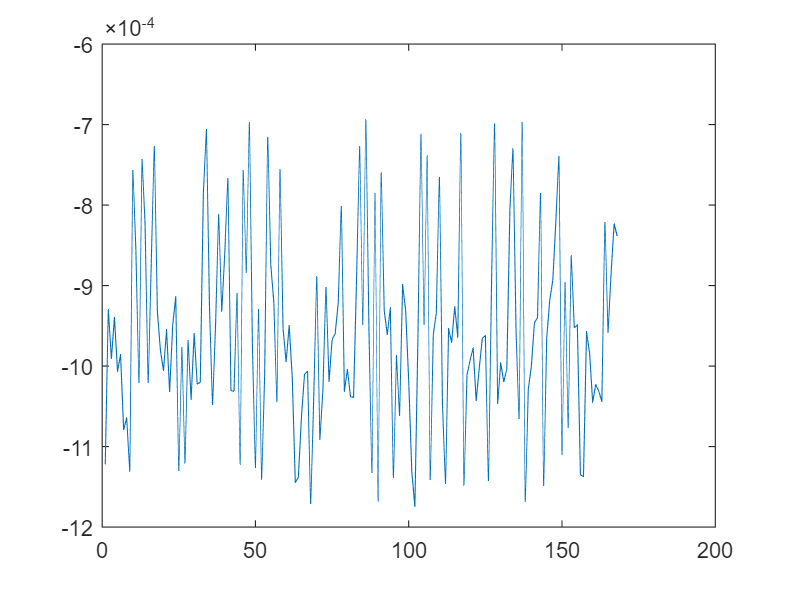


figure
plot(c_list)

% A = (max(Vout_array(:)) - min(Vout_array(:)))/2
% C = mean(Vout_array(:))
% C = (max(Vout_array(:)) + min(Vout_array(:)))
A = mean(abs(a_list))

A = 1.8196

C = mean(c_list)

C = -9.5904e-04

Lm = zeros(1, 2^N-1);
for i = 1: 2^N-1
    Lm(i) = C - A*cos(pi*quan_tb.Cdf(i));
end
delta = (Lm(end) - Lm(1)) / (2^N-2)

delta = 1.0987e-04

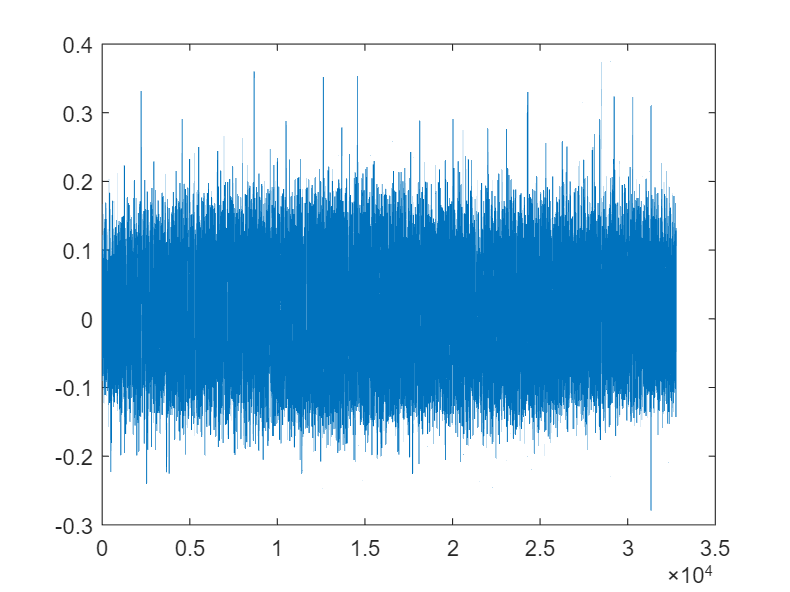


DNL = (diff(Lm) / delta) - 1;
plot(DNL)

INL = cumsum(DNL)

INL =    -0.0221    0.0989    0.0932    0.0242    0.0001    0.1027    0.0493    0.0100    0.0549   -0.0294   -0.0257   -0.0293    0.0852    0.0495    0.1357    0.1610    0.0716    0.0414   -0.0279    0.0112   -0.0145    0.1519    0.1994    0.1870    0.2597    0.1974    0.2938    0.3188    0.3031    0.2496    0.2414    0.2673    0.3101    0.3121    0.3058    0.2749    0.2238    0.3238    0.3068    0.3681    0.3830    0.4038    0.3209    0.2613    0.2442    0.3457    0.3109    0.3118    0.3650    0.3050


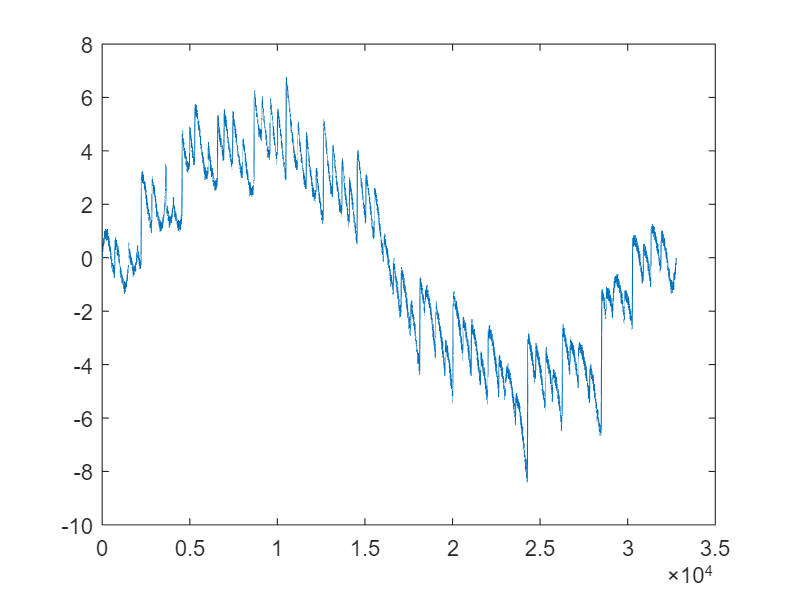

plot(INL)

% grid on
max(abs(DNL))

ans = 0.3725

% for i = 1:2^N-2
%     INL(i) = (Lm(i) - Lm(1)) / delta - i;
% end
% plot(INL)
max(abs(INL))

ans = 8.3966

function data_N4 = ReadData(filename)
    LSB_sub = 1.8 / 2^5;
    data_origin = importdata(filename);
    data_bin = dec2bin(data_origin);
    
    % 读取符号位和数值
    data_sign = bin2dec(data_bin(:,1));
    data_value = bin2dec(data_bin(:,2:end));
    data_sign(data_sign==1) = -1;
    data_sign(data_sign==0) = 1; 
    
    data_value = data_value .* data_sign;
    
    % 将串行输出的数据转化为并行输出的数据
    len = length(data_value) / 4;
    data_N4 = reshape(data_value, [4, len])';

    data_N4 = data_N4 * LSB_sub;
end

function Vout_calib = Calibration(data_N4, Gain)
    Vout_calib = zeros(length(data_N4), 1);
    for i = 1:length(data_N4)
        Vout_calib(i) = Calib_Gain(data_N4(i,:), Gain);
    end
end
